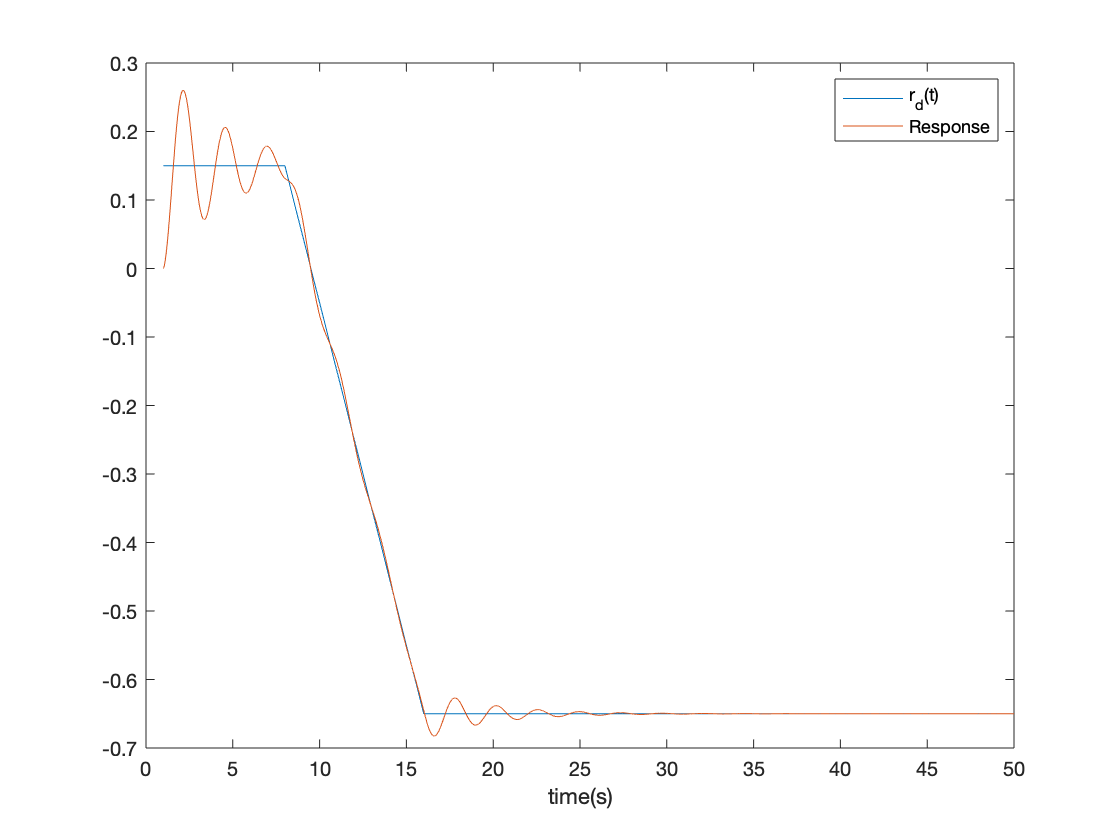

% Initialize:
u_k_1   = 0;
e_k_1   = 0;
d_prev  = 0;
delta_t = 0.01;
theta   = 0;
d_k     = 0;
d_dot   = 0;
d_mem   = [];
r_mem   = [];

% Control system:
for t = 1:delta_t:50
    r_d          = trajectory(t);
    e_k          = r_d - d_prev;
    u_k          = discrete_PD_controller(e_k, e_k_1, u_k_1) + input_disturbance();
    [d_ddot, theta_dot] = nonlinear_fn(u_k, d_dot, theta);
    
    d_dot  = d_dot + d_ddot*delta_t;
    d_k    = d_k + d_dot*delta_t;
    theta  = theta + theta_dot*delta_t;
    theta = min(max(theta, -pi/2),pi/2);
    
    % Update:
    e_k_1  = e_k;
    u_k_1  = u_k;
    d_prev = d_k + sensor_noise();
    
    % Save:
    r_mem  = [r_mem r_d];
    d_mem  = [d_mem d_k];
end

% Plot graphs:
plot(1:delta_t:50, r_mem)      
hold on
plot(1:delta_t:50, d_mem)
legend('r_d(t)', 'Response')
xlabel('time(s)')